clear, clc, close all

--------------------
Robot: (3 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1         arm1         jnt1     revolute             base(0)   arm2(2)  
   2         arm2         jnt2     revolute             arm1(1)   arm3(3)  
   3         arm3         jnt3        fixed             arm2(2)   
--------------------


ans =   Axes (Primary) with properties:

             XLim: [-2.5000 2.5000]
             YLim: [-2.5000 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


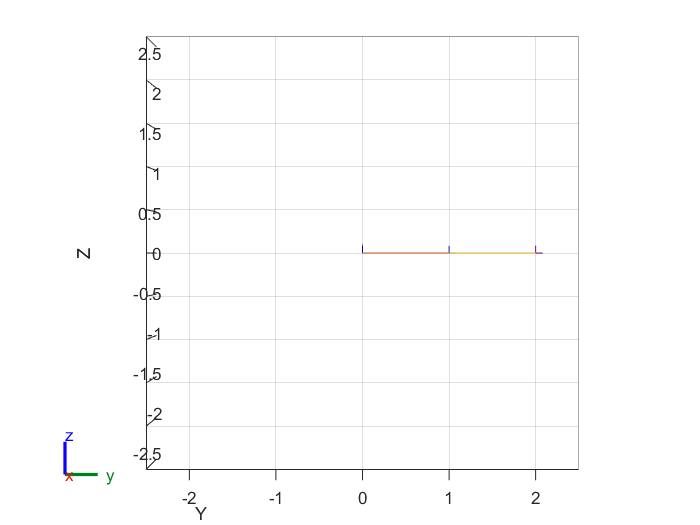

% Create robot
robot = create_robot_tree(1);

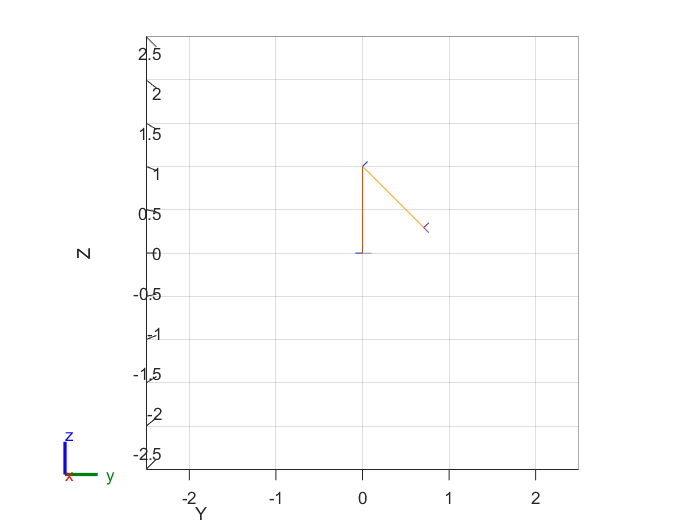

robot.Gravity = [0 0 -9.81];
config = homeConfiguration(robot);
pose = [pi/2; -3*pi/4];
show(robot,pose);
xlim([-.01,.01])
view(90,0)

nJoints = 2;
% gui = interactiveRigidBodyTree(robot,"MarkerScaleFactor",0.25);
m1 = 1; 
m2 = 1;
L1 = 1;
L2 = 1;
l1 = 0.5;
l2 = 0.5;
g = 9.81;

% Test simulation of nonlinear robot dynamics
u_test = @(t) 0*t;
t_free_sim = [0,5];
x0 = [pose;zeros(nJoints,1)];
[t_test,x_test] = sim_robot(robot,u_test,x0,t_free_sim);

% Animate response
% q_test = x_test(:,1:nJoints);
% count = size(q_test,1);
% rate = 0.01;
% show(robot,q_test(1,:)');
% xlim([-.01,.01])
% view(90,0)
% while true
%     for i = 1:count
%         show(robot,q_test(i,:)','PreservePlot',false);
%         xlim([-.01,.01])
%         view(90,0)
%         drawnow
%         pause(rate);
%     end
%     pause(0.5);
% end % Need to manually stop execution here

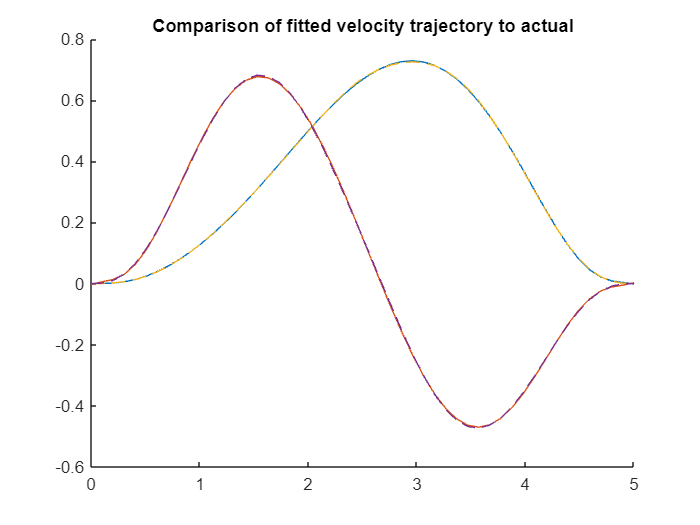

% Create trajectory
ik = inverseKinematics('RigidBodyTree',robot);
% ignore orientation for now
weights = [0 0 0 1 1 1];

% Create waypoints:
xi = [0 1 0.5];
xw = [0 0 1.75];
xf = [0 -1 1];
x = [xi; xw; xf];

% Equally spaced time points for each waypoint, can change this
t_fin = 5;
n = size(x,1);
tpts = linspace(0,t_fin,n);

% Timing parameter
r = .1; % This affects how many discrete points there are in the 
% trajectory, and is the main driver of error in the inverse dynamics
% controller below

% Solve for cubic trajectory
% [qt, qtd, qtdd, tpp] = create_cubic_traj(robot,weights,x,tpts,r,pose);

% Solve for minimum jerk trajectory
[qt,qtd,qtdd,qtddd,tpp,tPoints,tSamples] = create_minjerk_traj(robot,weights,x,tpts,r,pose);

% Actually going to be interested in piecewise polynomial tpp, 
% which can be evaluated at an arbitrary time

% Also need velocity of the trajectory as a function of time
order = 10; % Is 10 good enough?
qdp1 = polyfit(tSamples,qtd(1,:),order); 
qdp2 = polyfit(tSamples,qtd(2,:),order);
% Compare true to fitted graphically
figure()
hold on
title("Comparison of fitted velocity trajectory to actual")
plot(tSamples,polyval(qdp1,tSamples))
plot(tSamples,polyval(qdp2,tSamples))
plot(tSamples,qtd,'--')


% Animate Trajectory
% animate_traj(robot,qt,r) % Need to manually stop execution

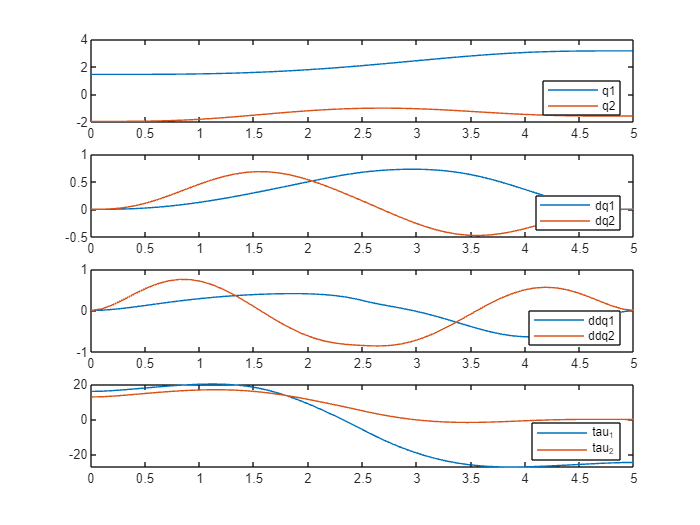

% Create an inverse dynamics controller for the trajectory
% Plot trajectory
n_traj = size(qt,2);
xt = linspace(0,t_fin,n_traj);
figure
subplot(4,1,1)
plot(xt,qt)
legend("q1","q2",'Location','southeast')
subplot(4,1,2)
plot(xt,qtd)
legend("dq1","dq2",'Location','southeast')
subplot(4,1,3)
plot(xt,qtdd)
legend("ddq1","ddq2",'Location','southeast')

% This gets torques required for the acceleration at each trajectory point
tau_t = zeros(size(qt));
for i=1:n_traj
    ti = i/n_traj*t_fin;
    tau_t(:,i) = inverse_dynamics_controller(ti,robot,qt,qtd,qtdd,xt);
end
subplot(4,1,4)
plot(xt,tau_t)
legend("tau_1","tau_2",'Location','southeast')

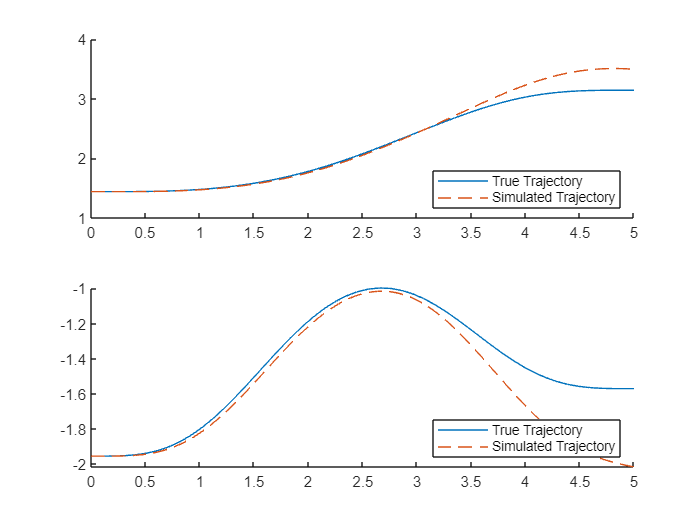

% Test for the robot
k_null = @(t) zeros(2,4); % No lqr gains at first
u_traj = @(t) inverse_dynamics_controller(t,robot,qt,qtd,qtdd,xt);
q_traj = @(t) [ppval(tpp,t)]; % Disregard velocity trajectory
q_traj_full = @(t) [ppval(tpp,t); polyval(qdp1,t); polyval(qdp2,t)];

x0 = [qt(:,1);0;0]; % No starting position error
opts = odeset('RelTol',1e-4,'AbsTol',1e-6); % These settings give good results. It's sensitive to number of time steps, obviously
% opts = [];
[t_sim_ID,x_sim_ID] = sim_robot_lqr(robot,k_null,q_traj,u_traj,x0,[0,t_fin],opts);
q_sim_ID = x_sim_ID(:,1:nJoints)';
% animate_traj(robot,q_sim,0.01)

% Plot trajectory from controller vs. true desired trajecory
figure
title("Inverse Dynamics Controller")
subplot(2,1,1)
hold on
plot(tSamples,qt(1,:))
plot(t_sim_ID,q_sim_ID(1,:),'--')
legend("True Trajectory","Simulated Trajectory",'Location','southeast')
subplot(2,1,2)
hold on
plot(tSamples,qt(2,:))
plot(t_sim_ID,q_sim_ID(2,:),'--')
legend("True Trajectory","Simulated Trajectory",'Location','southeast')


% MENTION LIMITATIONS OF FEEDBACK LINEARIZATION(?) IN PAPER?

% This blo,ck gets the A,B matrices as functitons of state
% q and input vars u
[q_ddot, q_dot, q, u, vars] = robot_arm_dynamics();
[A,B,dq,du] = linearize_around_state(q_ddot,q,u);

% Set parameters
params = [m1 m2 L1 L2 l1 l2 g]; % Is g positive or negative??
A2 = subs(A,vars,params);
B2 = subs(B,vars,params);

% Set trajectory/input variables
% can ignore velocity component because linearization doesn't depend on it
vars2 = [formula(q);formula(u)];
eval_vars = @(t) [q_traj(t);u_traj(t)];

% Create A,B matrices as functions of time
At = @(t) eval_mat(A2,vars2,eval_vars,t);
nStates = size(At(0),1);
Bt = @(t) eval_mat(B2,vars2,eval_vars,t);
% Ct = @(t) [eye(nJoints), zeros(nJoints)];
Ct = @(t) eye(nStates);


% Grammian
% WcWo(At,Bt,Ct,[0 t_fin])

% Set lqr params
Q = @(t) diag([100000,100000,0,0]);                            
R = @(t) eye(nJoints);                         
S_tf = diag([100000,100000,0,0]); 
t_k = [0,t_fin];

% [time,L] = tvLQR(At,Bt,Q,R,S_tf,t_k);
% K_f = flip(L,3); % These are in reverse order
% time_f = flip(time);

% Test another way of trajectory LQR, lines up pretty well
linSys = @(t) [At(t), Bt(t)];
num_t = 300;
tlqr = linspace(0,t_fin,num_t);
Ql = Q(0);
Rl = R(0);
Soln = trajectoryLqr(tlqr,linSys,Ql,Rl,S_tf,1e-6);
Kl = reshape([Soln.K],[2,4,num_t]);
timel = [Soln.t];

% Now create gains as a function in time
% Kt = @(t) piecewise_gains(K_f,time_f,t); % 2x4 gain matrix
Kt = @(t) piecewise_gains(Kl,timel,t);

% Set initial state
x0 = [qt(:,1);0;0];

opts = odeset('RelTol',1e-4,'AbsTol',1e-6);
% opts = [];
[t_sim,x_sim] = sim_robot_lqr(robot,Kt,q_traj_full,u_traj,x0,[0,t_fin],opts);
r = 0.01;
q_sim = x_sim(:,1:nJoints)';

% animate_traj(robot,q_sim,r)

% Backcalculate gains used and close loop A matrices
taus = zeros(nJoints,size(t_sim,1));
Acl = zeros(nStates,nStates,size(t_sim,1));
for i=1:length(t_sim)
    ti = t_sim(i);
    xi = x_sim(i,:)';
    
    q0_t = q_traj(ti);
    K_t = Kt(ti);
    u_t = double(u_traj(ti));
    
    if length(q0_t) == nJoints % This means no velocity in q_traj
        K_t(:,n+1:end) = 0; % Disregards velocity differences
        dx = (xi-[q0_t;0;0]);
    elseif length(q0_t) == nStates
        dx = (xi-q0_t);
    end
    G = double(K_t*dx);
    tau = u_t + G;
    taus(:,i) = tau;

    Acl(:,:,i) = At(ti)-Bt(ti)*K_t;
end

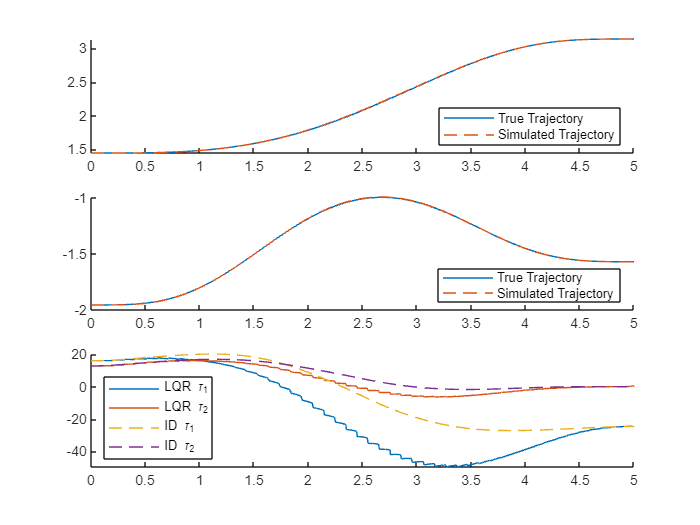

% Plot trajectory from controller vs. true desired trajecory
figure()
subplot(3,1,1)
hold on
plot(tSamples,qt(1,:))
plot(t_sim,q_sim(1,:),'--')
legend("True Trajectory","Simulated Trajectory",'Location','southeast')
subplot(3,1,2)
hold on
plot(tSamples,qt(2,:))
plot(t_sim,q_sim(2,:),'--')
legend("True Trajectory","Simulated Trajectory",'Location','southeast')
subplot(3,1,3)
hold on
plot(t_sim,taus)
plot(xt,tau_t,'--')
legend("LQR \tau_1","LQR \tau_2","ID \tau_1","ID \tau_2",'Location','southwest')

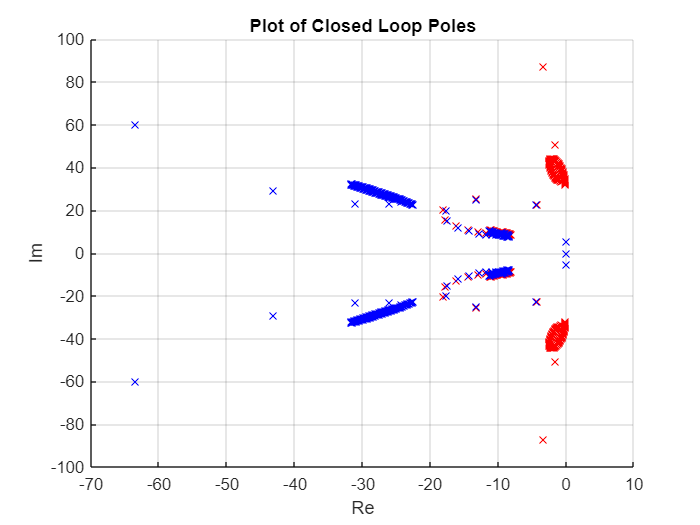


% PLOT SYSTEM POLES OVER TIME IN THIS SYSTEM
% TODO change color through time??

figure()
hold on
grid on
for i=1:2:size(Acl,3)
    rt = roots(charpoly(Acl(:,:,i)));
    plot(real(rt),imag(rt),'rx');
end

t_plot = timel;
K_plot = Kl;
% t_plot = time_f;
% K_plot = K_f;

ctrbs = zeros(nStates,nStates*nJoints,size(t_plot,2));
conds = zeros(1,size(t_plot,2));
for i=1:size(t_plot,2)
    ti = t_plot(i);
    Ki = K_plot(:,:,i);
    rt = roots(charpoly(At(ti)-Bt(ti)*Ki));
    ctrbi = ctrb(At(ti),Bt(ti));
    ctrbs(:,:,i) = ctrbi;
    conds(i) = cond(ctrbi);
    plot(real(rt),imag(rt),'bx');
end

title("Plot of Closed Loop Poles")
ylabel("Im")
xlabel("Re")

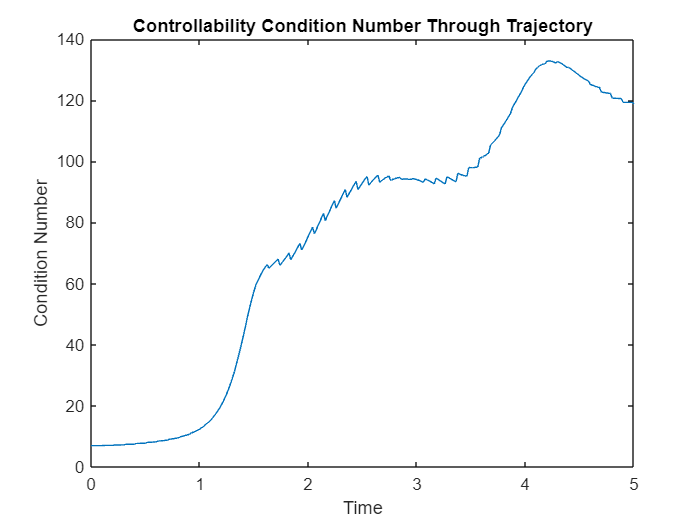


% Plot condition numbers of controllability
figure()
plot(t_plot,conds)
title("Controllability Condition Number Through Trajectory")
xlabel("Time")
ylabel("Condition Number")

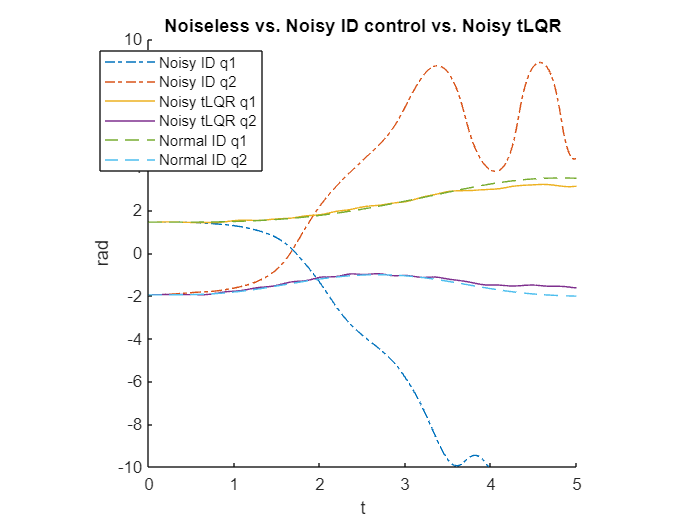

% Implement the discrete time extended kalman filter
rng(10);    % For repeatable results
dt = 0.025;     % seconds
t_k = 0:dt:t_fin;

inputNoise = diag([0 0 0.002 0.002]); % process noise cov. matrix, rad^2, (rad/s)^2
% outputNoise = diag([.01 .01]); % Measurement noise cov. matrix, rad^2
outputNoise = diag([.003 .003 .003 .003]); % Observe all states

H = Ct(0); % Measurement matrix, one obs. per joint

% 1. Initialize the state of the filter
xInitial = [qt(:,1);0;0]; % [q; q_dot]

% 2. Initialize our belief in the state, state error covariance P0
P0 = diag([.05,.05,.01,.01]); % m, m/s. TODO Initialize better

% Preallocate variables
numSteps = length(t_k);

% Use these for ID, perfect state knowledge
trueStatesID = NaN(nStates,numSteps);
trueStatesID(:,1) = xInitial;

% Use these for LQR, perfect state knowledge
trueStatesLQR = NaN(nStates,numSteps);
trueStatesLQR(:,1) = xInitial;

estimateStatesID = NaN(size(trueStatesID));
estimateStatesID(:,1) = xInitial;
measurementsID = NaN(size(H,1),numSteps); % What is first value?
% estErrorCov = NaN(nStates,nStates,numSteps);
% estErrorCov(:,:,1) = P0;

estimateStatesLQR = NaN(size(trueStatesLQR));
estimateStatesLQR(:,1) = xInitial;
measurementsLQR = NaN(size(H,1),numSteps); % What is first value?
% estErrorCovLQR = NaN(nStates,nStates,numSteps);
% estErrorCovLQR(:,:,1) = P0;

% Define state update and measurement models
robot_obs_model = @(x,w) H*x + w;
opts = [];
% Nonlinear update model using ode45. Starts at state x(t) and integrates
% to get xNext = x(t+dt). Need t to determine what time we are at in traj.
robot_st_model = @(x, dt, t) sim_robot_lqr(robot,k_null,q_traj,u_traj,x,[t,t+dt],opts);
robot_st_LQR_model = @(x, dt, t) sim_robot_lqr(robot,Kt,q_traj,u_traj,x,[t,t+dt],opts);

% Get true state and measurements
for i = 2:length(t_k)
    if i ~= 1
        ti = t_k(i);
        v = sqrt(inputNoise)*randn(size(inputNoise,1),1);
        
        % Update ID
        [t_st,x_st] = robot_st_model(trueStatesID(:,i-1),dt,ti);
        trueStatesID(:,i) = x_st(end,:)' + v;
        
        % Update ID with LQR
        [t_st,x_st] = robot_st_LQR_model(trueStatesLQR(:,i-1),dt,ti);
        trueStatesLQR(:,i) = x_st(end,:)' + v;
    end

    w = sqrt(outputNoise)*randn(size(outputNoise,1),1);
    measurementsID(:,i) = robot_obs_model(trueStatesID(:,i),w);
end

figure()
hold on
title("Noiseless vs. Noisy ID control vs. Noisy tLQR")
plot(t_k,trueStatesID(1:2,:),'-.')
plot(t_k,trueStatesLQR(1:2,:))
plot(t_sim_ID,q_sim_ID,'--')
xlabel("t")
ylabel("rad")
ylim([-10,10])
legend("Noisy ID q1","Noisy ID q2","Noisy tLQR q1","Noisy tLQR q2","Normal ID q1","Normal ID q2",'Location','best')
axis square

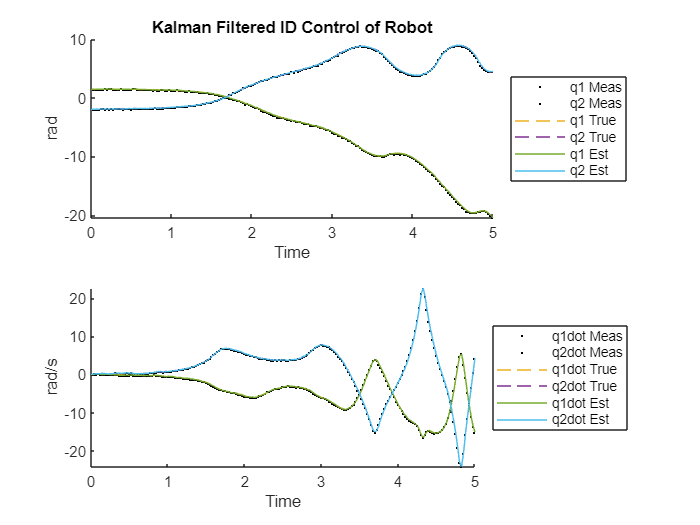

% Apply Kalman Filter to noisy process
% Predict
% 
% 1. Use process model to predict state at the next time step
% 2. Adjust belief to account for the uncertainty in prediction    
%
% Update
% 
% 1. Get a measurement and associated belief about its accuracy
% 2. Compute residual between estimated state and measurement
% 3. Compute scaling factor based on whether the measurement
% or prediction is more accurate
% 4. set state between the prediction and measurement based 
% on scaling factor
% 5. update belief in the state based on how certain we are 
% in the measurement

% Create function for finding linear update matrix F
q_ddot_subs = subs(q_ddot,vars,params);
F_q = formula(jacobian(q_ddot_subs,[q;q_dot])); % Nonlinear Jacobian of analytic q_ddot
F_q = [zeros(nJoints),eye(nJoints) ; F_q]; % Jacobian of q_ddot w.r.t itself is 1

% Run with no additional LQR control
Pi = P0;
for i=2:length(t_k)
    % Prediction
    ti = t_k(i);
    x_prev = estimateStatesID(:,i-1);
    [t_st,x_st] = robot_st_model(x_prev,dt,ti);
    x_pred = x_st(end,:)';
    u_ti = double(u_traj(ti));
    F_state = double(subs(F_q,[formula(q); formula(q_dot);formula(u)],[x_pred;u_ti]));
    P_bar = F_state*Pi*F_state' + inputNoise;
    
    % Update
    zi = measurementsID(:,i); % Measurement
    yi = zi - H*x_pred; % Residual
    Gi = P_bar*H'*inv(H*P_bar*H'+outputNoise); % Gain
    x_est = x_pred + Gi*yi; % State mean est. update
    estimateStatesID(:,i) = x_est;
    Pi = (eye(nStates) - Gi*H)*P_bar; % Update est. state error cov.
end

% Plot true vs. estimated vs. measured
figure()
subplot(2,1,1)
hold on
plot(t_k,measurementsID(1:nJoints,:),'k.','MarkerSize',4)
plot(t_k,trueStatesID(1:nJoints,:),'--')
plot(t_k,estimateStatesID(1:nJoints,:))
legend("q1 Meas","q2 Meas","q1 True","q2 True","q1 Est","q2 Est",'Location','eastoutside')
xlabel("Time")
ylabel("rad")
title("Kalman Filtered ID Control of Robot")
subplot(2,1,2)
hold on
if size(measurementsID,1) > nJoints
    plot(t_k,measurementsID(nJoints+1:end,:),'k.','MarkerSize',4)
end
plot(t_k,trueStatesID(nJoints+1:end,:),'--')
plot(t_k,estimateStatesID(nJoints+1:end,:))
if size(measurementsID,1) > nJoints
    legend("q1dot Meas","q2dot Meas","q1dot True","q2dot True","q1dot Est","q2dot Est",'Location','eastoutside')
else
    legend("q1dot True","q2dot True","q1dot Est","q2dot Est",'Location','eastoutside')
end
xlabel("Time")
ylabel("rad/s")

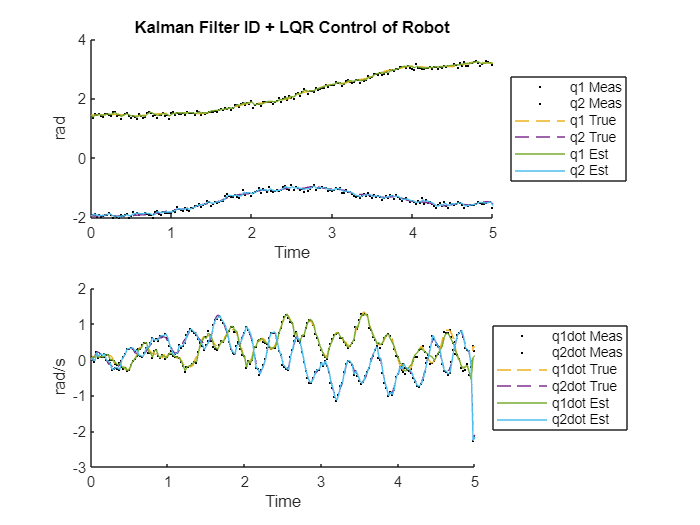

% Now run full system with LQR and Kalman filter
rng(20);

trueStatesFull = NaN(nStates,numSteps);
trueStatesFull(:,1) = xInitial;

estimateStatesFull = NaN(size(trueStatesFull));
estimateStatesFull(:,1) = xInitial;

measurementsFull = NaN(size(H,1),numSteps); % What is first value?

% Now run with additional LQR control. Do true state calc and measurement
% in loop.
Pi = P0;
for i=2:length(t_k)
    ti = t_k(i);
    
    % True state update
    if i ~= 1
        v = sqrt(inputNoise)*randn(size(inputNoise,1),1);
        % Update with LQR
        [t_st,x_st] = robot_st_LQR_model(trueStatesFull(:,i-1),dt,ti);
        trueStatesFull(:,i) = x_st(end,:)' + v;
    end

    % Prediction
    x_prev = estimateStatesFull(:,i-1);
    [t_st,x_st] = robot_st_LQR_model(x_prev,dt,ti); % Simulate nonlinear
    x_pred = x_st(end,:)'; % Get predicted value at ti
    u_ti = double(u_traj(ti)); % Get input value at ti
    F_state = double(subs(F_q,[formula(q); formula(q_dot);formula(u)],[x_pred;u_ti])); % Get lin. update matrix
    P_bar = F_state*Pi*F_state' + inputNoise;
    
    % Get measurement
    w = sqrt(outputNoise)*randn(size(outputNoise,1),1);
    zi = robot_obs_model(trueStatesFull(:,i),w);
    measurementsFull(:,i) = zi;

    % Update
    yi = zi - H*x_pred; % Residual
    Gi = P_bar*H'*inv(H*P_bar*H'+outputNoise); % Gain
    x_est = x_pred + Gi*yi; % State mean est. update
    estimateStatesFull(:,i) = x_est;
    Pi = (eye(nStates) - Gi*H)*P_bar; % Update est. state error cov.
end

% Plot true vs. estimated vs. measured
figure()
subplot(2,1,1)
hold on
plot(t_k,measurementsFull(1:nJoints,:),'k.','MarkerSize',4)
plot(t_k,trueStatesFull(1:nJoints,:),'--')
plot(t_k,estimateStatesFull(1:nJoints,:))
legend("q1 Meas","q2 Meas","q1 True","q2 True","q1 Est","q2 Est",'Location','eastoutside')
xlabel("Time")
ylabel("rad")
title("Kalman Filter ID + LQR Control of Robot")
subplot(2,1,2)
hold on
if size(measurementsFull,1) > nJoints
    plot(t_k,measurementsFull(nJoints+1:end,:),'k.','MarkerSize',4)
end
plot(t_k,trueStatesFull(nJoints+1:end,:),'--')
plot(t_k,estimateStatesFull(nJoints+1:end,:))
if size(measurementsFull,1) > nJoints
    legend("q1dot Meas","q2dot Meas","q1dot True","q2dot True","q1dot Est","q2dot Est",'Location','eastoutside')
else
    legend("q1dot True","q2dot True","q1dot Est","q2dot Est",'Location','eastoutside')
end
xlabel("Time")
ylabel("rad/s")

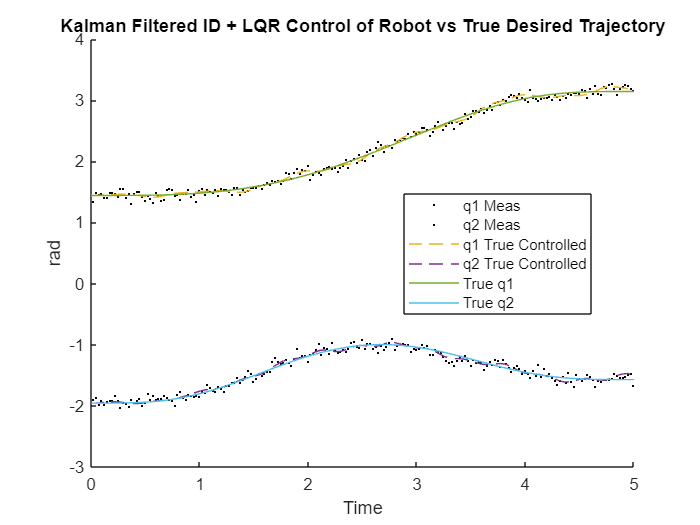


% Plot True Trajectory vs. Controlled True Trajectory
figure()
hold on
plot(t_k,measurementsFull(1:nJoints,:),'k.','MarkerSize',4)
plot(t_k,trueStatesFull(1:nJoints,:),'--')
plot(xt,qt)
legend("q1 Meas","q2 Meas","q1 True Controlled","q2 True Controlled","True q1","True q2",'Location','best')
xlabel("Time")
ylabel("rad")
title("Kalman Filtered ID + LQR Control of Robot vs True Desired Trajectory")

qFull = trueStatesFull(1:nJoints,:);
animate_traj(robot,qFull,dt)